%% ================================================
%  ONN Physical Layer - Hiyerarşik MZI Monte Carlo Simülasyonu
%  AI Processor Design Project - Layer 1
%  Gürültü Modeli: Global + Lokal (Statik) + Termal (Dinamik) + Üretim Hataları
%% ================================================

clearvars; clc; close all;

%% --- PARAMETRELER ---
% Hiyerarşik Monte Carlo İterasyonları
N_MZI       = 100;             % Çip içindeki farklı MZI örneklem sayısı (Cihaz/Lokal Seviye)
N_time      = 100;             % Her MZI için anlık ölçüm sayısı (Çıkarım/Dinamik Seviye)
N_phi       = 1000;            % Faz açısı örnekleme noktası (Çözünürlük)
phi_vec     = linspace(0, 2*pi, N_phi);  % [0, 2π] arası

% Hiyerarşik Gürültü Parametreleri [rad]
sigma_global_phase  = 0.05;    % Çip geneli statik hata (Wafer-level)
sigma_local_phase   = 0.12;    % Cihaza özel statik hata (Device-level)
sigma_thermal       = 0.20;    % Anlık termal faz dalgalanması (Zamana bağlı)

% Fiziksel Üretim Hataları
sigma_split_angle   = 0.06;    % X-Kavşağı üretim hatası std [rad] 
alpha_IL            = 0.12;    % Insertion loss (güç kaybı)

%% --- FONKSİYONLAR ---
% MZI transfer matrisi hesaplayıcı (Trigonometrik Beam Splitter)
getMZI = @(phi, d_split_angle, il) ...
    il .* ...
    ([cos(pi/4 + d_split_angle), 1j*sin(pi/4 + d_split_angle); ...
      1j*sin(pi/4 + d_split_angle), cos(pi/4 + d_split_angle)]) * ...
    [exp(1j*phi), 0; 0, 1] * ...
    ([cos(pi/4 + d_split_angle), 1j*sin(pi/4 + d_split_angle); ...
      1j*sin(pi/4 + d_split_angle), cos(pi/4 + d_split_angle)]);

%% --- HİYERARŞİK MONTE CARLO SİMÜLASYONU ---
fprintf('Monte Carlo başlıyor: %d MZI x %d Zaman Adımı x %d faz noktası...\n', N_MZI, N_time, N_phi);

Monte Carlo başlıyor: 100 MZI x 100 Zaman Adımı x 1000 faz noktası...



% 1) GLOBAL VARYASYON: Simülasyonun en başında çip için 1 kez belirlenir.
eps_global = sigma_global_phase * randn();
fprintf('>> Simüle edilen çip için Global Faz Sapması: %.4f rad\n', eps_global);

>> Simüle edilen çip için Global Faz Sapması: -0.0464 rad



% CSV için Ayrıştırılmış Sonuç Matrisleri
mu_weight     = zeros(1, N_phi); 
sigma_static  = zeros(1, N_phi); % Üretim hatalarının (kalıcı) varyansı
sigma_dynamic = zeros(1, N_phi); % Termal hataların (anlık) varyansı
sigma_total   = zeros(1, N_phi); % Görselleştirme için toplam varyans

for k = 1:N_phi
    phi_nom = phi_vec(k);     
    
    mzi_means = zeros(N_MZI, 1); % Her MZI'ın kendi ortalama çıktısı (Statik Karakter)
    mzi_stds  = zeros(N_MZI, 1); % Her MZI'ın kendi termal titreşimi (Dinamik Karakter)
    
    for m = 1:N_MZI
        % 2) LOKAL VARYASYON (Statik): Fabrikadan çıkan cihazın kaderi
        eps_local = sigma_local_phase * randn();
        d_split_angle = sigma_split_angle * randn(); 
        il_factor = sqrt(1 - alpha_IL * rand());     
        
        temporal_samples = zeros(N_time, 1);
        
        for t = 1:N_time
            % 3) DİNAMİK GÜRÜLTÜ (Termal): Çıkarım anındaki ısınma/soğuma
            eps_dynamic = sigma_thermal * randn();
            
            % Toplam Hiyerarşik Faz
            phi_noisy = phi_nom + eps_global + eps_local + eps_dynamic;
            
            % Gürültülü MZI Matrisi ve Diferansiyel Çıktı
            U = getMZI(phi_noisy, d_split_angle, il_factor);
            temporal_samples(t) = abs(U(1,1))^2 - abs(U(2,1))^2;
        end
        
        % Bu spesifik MZI'ın zaman içindeki ortalaması ve sapması
        mzi_means(m) = mean(temporal_samples); 
        mzi_stds(m)  = std(temporal_samples);  
    end
    
    % İSTATİSTİKSEL AYRIŞTIRMA (PyTorch'a Gidecek Veriler)
    mu_weight(k)     = mean(mzi_means);         % İdeal gerçekleşen ağırlık
    sigma_static(k)  = std(mzi_means);          % MZI'lar arası kalıcı üretim varyasyonu
    sigma_dynamic(k) = mean(mzi_stds);          % Ortalama anlık termal varyasyon
    
    % Hata paylarının istatistiksel toplamı (Grafikler için)
    sigma_total(k)   = sqrt(sigma_static(k)^2 + sigma_dynamic(k)^2); 
end

fprintf('Simülasyon tamamlandı.\n');

Simülasyon tamamlandı.



%% --- CSV ÇIKTISI ---
output_table = table(phi_vec', mu_weight', sigma_static', sigma_dynamic', ...
    'VariableNames', {'phi_rad', 'mu_weight', 'sigma_static', 'sigma_dynamic'});

writetable(output_table, 'mzi_lookup_table.csv');
fprintf('CSV kaydedildi: mzi_lookup_table.csv\n');

CSV kaydedildi: mzi_lookup_table.csv


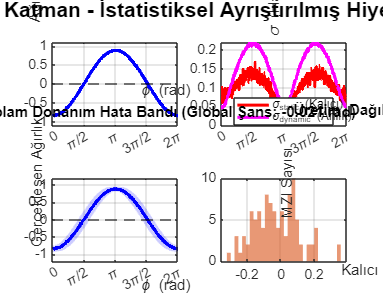


%% --- GÖRSELLEŞTİRME ---
figure('Name', 'MZI Hierarchical Monte Carlo', 'NumberTitle', 'off', 'Position', [100, 100, 1000, 800]);

% Plot 1: Transfer Fonksiyonu
subplot(2,2,1);
plot(phi_vec, mu_weight, 'b-', 'LineWidth', 2);
xlabel('\phi (rad)'); ylabel('Ağırlık (\mu)');
title('Diferansiyel Ağırlık Çıktısı');
xticks([0 pi/2 pi 3*pi/2 2*pi]); xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi'});
yline(0, 'k--'); ylim([-1.1 1.1]); grid on;

% Plot 2: Statik ve Dinamik Hataların Kıyası
subplot(2,2,2);
plot(phi_vec, sigma_static, 'r-', 'LineWidth', 2); hold on;
plot(phi_vec, sigma_dynamic, 'm-', 'LineWidth', 2);
xlabel('\phi (rad)'); ylabel('\sigma (Hata Payı)');
title('Statik (Üretim) vs Dinamik (Termal) Gürültü');
legend('\sigma_{static} (Kalıcı)', '\sigma_{dynamic} (Anlık)', 'Location', 'best');
xticks([0 pi/2 pi 3*pi/2 2*pi]); xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi'});
grid on;

% Plot 3: Toplam Hata Bandı
subplot(2,2,3);
fill([phi_vec, fliplr(phi_vec)], ...
     [mu_weight + sigma_total, fliplr(mu_weight - sigma_total)], ...
     'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none'); hold on;
plot(phi_vec, mu_weight, 'b-', 'LineWidth', 2);
xlabel('\phi (rad)'); ylabel('Gerçekleşen Ağırlık');
title(sprintf('Toplam Donanım Hata Bandı (Global Şans: %.3f rad)', eps_global));
xticks([0 pi/2 pi 3*pi/2 2*pi]); xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi'});
yline(0, 'k--'); ylim([-1.2 1.2]); grid on;

% Plot 4: Örneklem Histogramı (π/2 Noktası)
phi_demo_idx = round(N_phi / 4);  
phi_demo = phi_vec(phi_demo_idx);
% Demo için MZI ortalamalarının dağılımını çiziyoruz (Üretim Varyasyonunu görmek için)
subplot(2,2,4);
mzi_means_demo = zeros(N_MZI, 1);
for m = 1:N_MZI
    eps_local = sigma_local_phase * randn();
    d_split_angle = sigma_split_angle * randn();
    il_factor = sqrt(1 - alpha_IL * rand());
    temporal_samples_demo = zeros(N_time, 1);
    for t = 1:N_time
        eps_dynamic = sigma_thermal * randn();
        U = getMZI(phi_demo + eps_global + eps_local + eps_dynamic, d_split_angle, il_factor);
        temporal_samples_demo(t) = abs(U(1,1))^2 - abs(U(2,1))^2;
    end
    mzi_means_demo(m) = mean(temporal_samples_demo);
end
histogram(mzi_means_demo, 30, 'FaceColor', '#D95319', 'EdgeColor', 'none');
xlabel('Kalıcı MZI Ağırlıkları'); ylabel('MZI Sayısı');
title(sprintf('Üretim Dağılımı (\\phi = %.2f rad)', phi_demo));
grid on;

sgtitle('ONN Fiziksel Katman - İstatistiksel Ayrıştırılmış Hiyerarşik Model', 'FontSize', 14, 'FontWeight', 'bold');